load('CAS_11323wt.linkedTracks.mat');
wildT = linkedTracks;
load('CAS_11323transgenic.linkedTracks.mat')
transgen = linkedTracks;
load("cas.stim")
CAS = cas;
Types = {wildT,transgen};
Types_labels = {'Wild Type','Transgenic'};

for j = 1:length(CAS)
    light_starts(j) = CAS(j, 1);
    light_ends(j) = CAS(j, 2);
end
    

avg

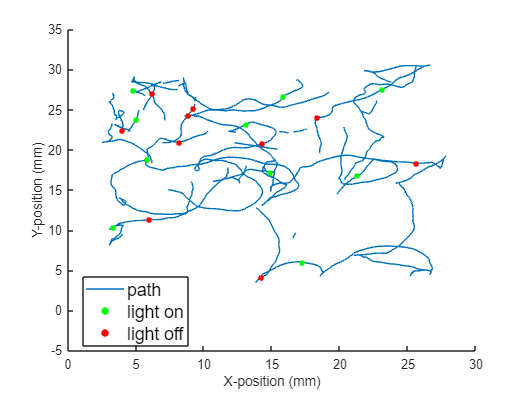

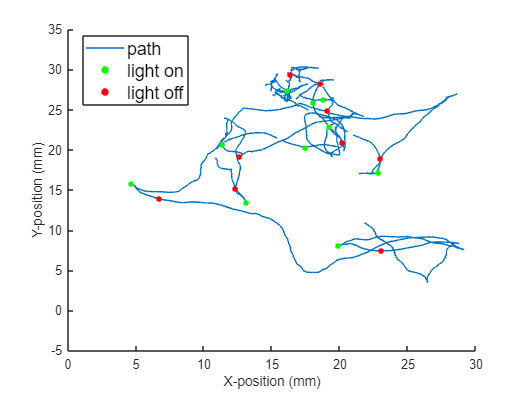

for i = 1:length(Types)
    %wildType
    num_animals = length(Types{i});
    % the frame rate should be the same for all animals/tracks, we will
    % just read from one of them
    FrameRate = Types{i}(1).FrameRate;
    times = arrayfun(@(z) max(z.Time), Types{i});
    max_frames = max(times)*FrameRate;

    xpos = zeros(num_animals, max_frames);
    ypos = zeros(num_animals, max_frames);

    xpos(1:num_animals, 1:max_frames) = nan;
    ypos(1:num_animals, 1:max_frames) = nan;

    for animal_index = 1:length(Types{i})
        startFrame = Types{i}(animal_index).Frames(1);
        endFrame = Types{i}(animal_index).Frames(end);
        xpos(animal_index, startFrame:endFrame) = Types{i}(animal_index).SmoothX(:)*Types{i}(animal_index).PixelSize;
        ypos(animal_index, startFrame:endFrame) = Types{i}(animal_index).SmoothY(:)*Types{i}(animal_index).PixelSize;
    end

    instance = 6;
    figure;
    hold on
    plot(Types{i}(instance).SmoothX*Types{i}(animal_index).PixelSize, Types{i}(instance).SmoothY*Types{i}(animal_index).PixelSize)

    for j = 1:length(CAS)
        start = CAS(j, 1);
        end_ = CAS(j, 2);
        scatter(xpos(instance,round(start*3)), ypos(instance,round(start*3)), 20, 'green', 'filled');
        scatter(xpos(instance,round(end_*3)), ypos(instance,round(end_*3)), 20, 'red', 'filled');
    end

    xlabel("X-position (mm)")
    ylabel("Y-position (mm)")
    ylim([-5 35])
    lgd= legend('path','light on','light off',location='best');
    fontsize(lgd,14,'points')
    hold off
    avgXpos = mean(xpos, "omitnan");
    avgYpos = mean(ypos, "omitnan");
end

for speed:

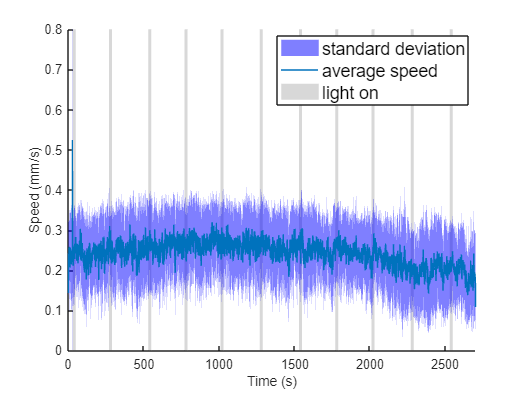

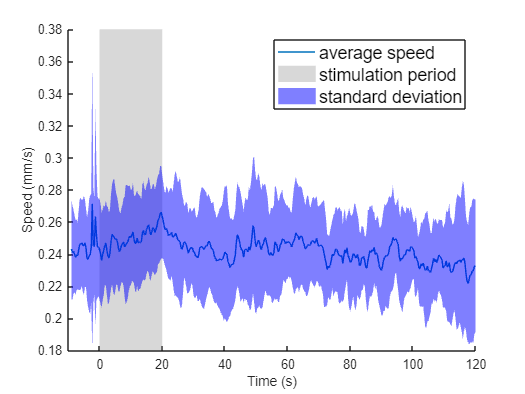

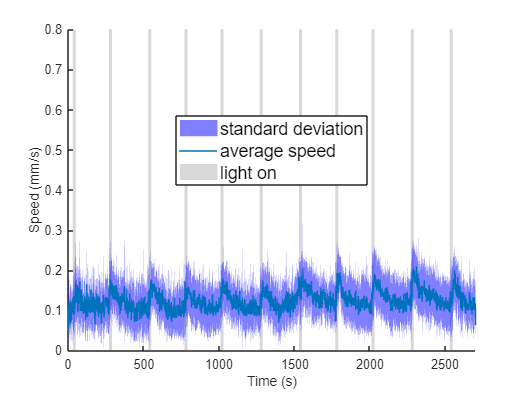

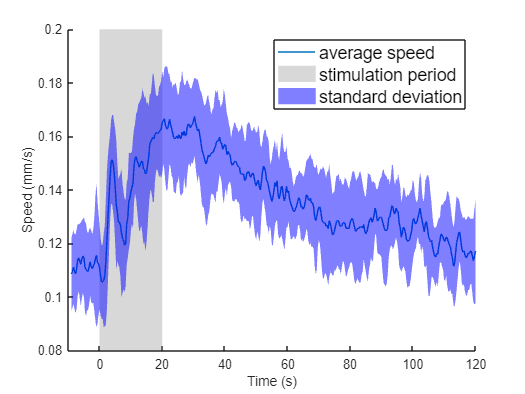

for i = 1:length(Types)
    num_animals = length(Types{i});
    speed = zeros(num_animals, max_frames);
    speed(1:num_animals, 1:max_frames) = nan;

    for animal_index = 1:length(Types{i})
        startFrame = Types{i}(animal_index).Frames(1);
        endFrame = Types{i}(animal_index).Frames(end);
        speed(animal_index, startFrame:endFrame) = Types{i}(animal_index).Speed(:);

    end

    avgspeed = mean(speed, "omitnan");

    light_times = light_ends-light_starts;
    light_time = light_times(1);

    avging_intl = round(10 + light_time + 100)*3;
    avg_speeds_duringstim = zeros(length(light_times), avging_intl);
    avg_speeds_duringstim(1:length(light_times), 1:avging_intl) = nan;
    
    for j = 1:length(light_times)
        before_light_start = round(light_starts(j)-10)*3;
        after_light_end = round(light_ends(j)+100)*3;
        avg_speeds_duringstim(j,1:avging_intl) = avgspeed(before_light_start:after_light_end-1);
    end


    avg_stim_speed = mean(avg_speeds_duringstim, "omitnan");

plot

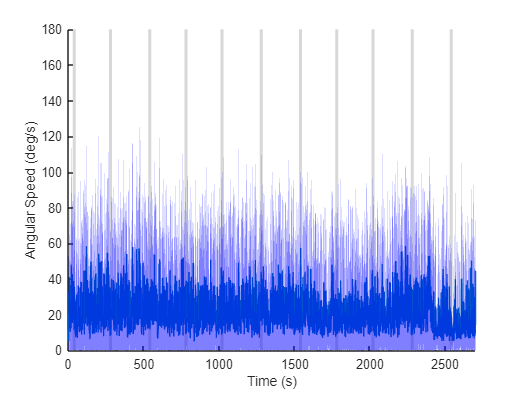

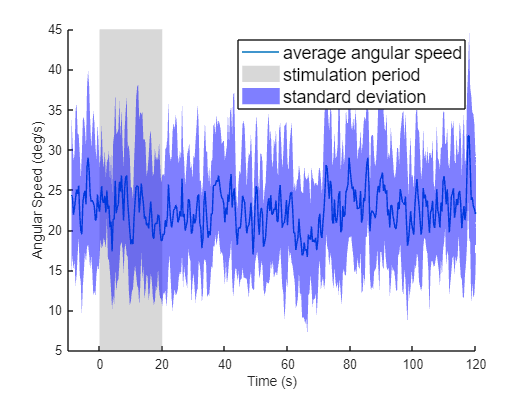

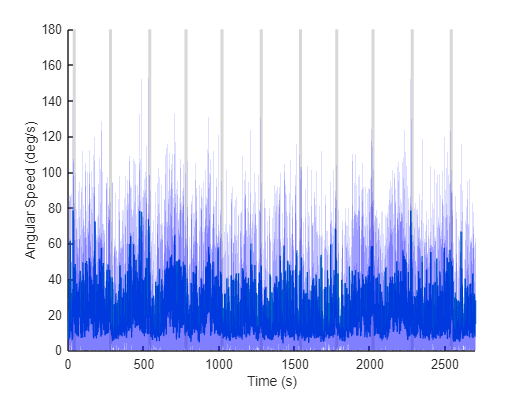

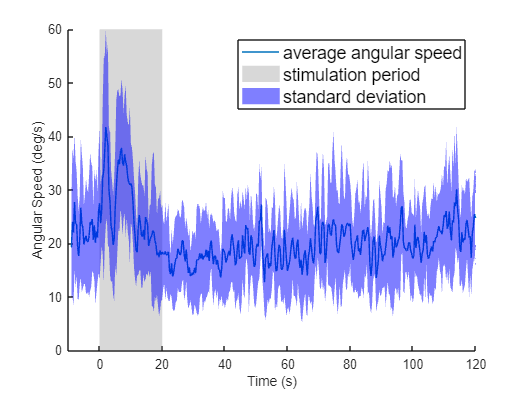

    time = linspace(1,2700,8100);
    figure;
    hold on
    std_speed = std(speed, "omitnan");
    patch([time flip(time)], [avgspeed-std_speed flip(avgspeed+std_speed)], 'b', 'FaceAlpha', .5 ,'EdgeColor', 'none');
    plot(time, avgspeed) %currently does not have correct time
    xregion(light_starts,light_ends);
    lgd= legend('standard deviation','average speed','light on',location='best');
    fontsize(lgd,14,'points')
    xlabel("Time (s)")
    ylabel("Speed (mm/s)")
    xlim([0 2700])
    ylim([0 .8])
    hold off

    figure;
    hold on
    avging_time= time(1:length(avg_stim_speed));
    plot(avging_time-10,avg_stim_speed);
    xregion(0,light_time);
    std_stim_speed = std(avg_speeds_duringstim, "omitnan");
    patch([avging_time-10 flip(avging_time-10)], [avg_stim_speed-std_stim_speed flip(avg_stim_speed+std_stim_speed)], 'b', 'FaceAlpha', .5 ,'EdgeColor', 'none');
    lgd= legend('average speed','stimulation period','standard deviation');
    fontsize(lgd,14,'points')
    xlabel("Time (s)")
    ylabel("Speed (mm/s)")
    xlim([-10 120])
    hold off



end

angular speed:

for i = 1:length(Types)
    num_animals = length(Types{i});
    angspeed = zeros(num_animals, max_frames);
    angspeed(1:num_animals, 1:max_frames) = nan;
    for animal_index = 1:length(Types{i})
        startFrame = Types{i}(animal_index).Frames(1);
        endFrame = Types{i}(animal_index).Frames(end);
        angspeed(animal_index, startFrame:endFrame) = Types{i}(animal_index).AngSpeed(:);
    end
    
    angspeed = abs(angspeed);

    avgangspeed = mean(angspeed, "omitnan");

plot angular speed:

    figure;
    hold on
    plot(time, avgangspeed) %currently does not have correct time
    std_angspeed = std(angspeed, "omitnan");
    patch([time flip(time)], [avgangspeed-std_angspeed flip(avgangspeed+std_angspeed)], 'b', 'FaceAlpha', .5 ,'EdgeColor', 'none');
    xlabel("Time (s)")
    ylabel("Angular Speed (deg/s)")
    xlim([0 2700])
    ylim([0 180])

    xregion(light_starts,light_ends);

    hold off

    light_times = light_ends-light_starts;
    light_time = light_times(1);

    avging_intl = round(10 + light_time + 100)*3;
    avg_ang_duringstim = zeros(length(light_times), avging_intl);
    avg_ang_duringstim(1:length(light_times), 1:avging_intl) = nan;
    
    for j = 1:length(light_times)
        before_light_start = round(light_starts(j)-10)*3;
        after_light_end = round(light_ends(j)+100)*3;
        avg_ang_duringstim(j,1:avging_intl) = avgangspeed(before_light_start:after_light_end-1);
    end


    avg_stim_speed = mean(avg_ang_duringstim, "omitnan");

    figure;
    hold on
    avging_time= time(1:length(avg_stim_speed));
    plot(avging_time-10,avg_stim_speed);
    xregion(0,light_time);
    std_stim_speed = std(avg_ang_duringstim, "omitnan");
    patch([avging_time-10 flip(avging_time-10)], [avg_stim_speed-std_stim_speed flip(avg_stim_speed+std_stim_speed)], 'b', 'FaceAlpha', .5 ,'EdgeColor', 'none');
    lgd= legend('average angular speed','stimulation period','standard deviation');
    fontsize(lgd,14,'points')
    xlabel("Time (s)")
    ylabel("Angular Speed (deg/s)")
    xlim([-10 120])
    hold off


end




functions from rec:

% function [averageSpeed, speeds] = findAvgSpeed(N2_tracks)
% 
%     % findAvgSpeed() takes in the entire dataset in the form of a struct,
%     % and returns a vector that stores the motion speed averaged across all
%     % animals at each frame of the recording
%     
%     num_animals = length(N2_tracks);
%     % the frame rate should be the same for all animals/tracks, we will
%     % just read from one of them
%     FrameRate = N2_tracks(1).FrameRate;
%     times = arrayfun(@(z) max(z.Time), N2_tracks);
%     max_frames = max(times)*FrameRate;
%     
%     speeds = zeros(num_animals, max_frames);
%     for animal_index = 1:length(N2_tracks)
%         speeds(animal_index, :) = N2_tracks(animal_index).Speed(:);
%     end
%     averageSpeed  = mean(speeds, 1);
% 
% end
% 
% 
% function EventFrames = findReorientationFrames(N2_tracks)
% 
%     % findReorientations() takes in the entire dataset in the form of a struct,
%     % and returns a 1 x n cell where n is the total number of animals in the dataset,
%     % each cell contains a vector of frames where each animal makes a re-orientation
%     
%     EventFrames = cell(1,length(N2_tracks));
%     for j = 1:length(N2_tracks) % iterating throught each animal/track
%         if(~isempty(N2_tracks(j).Reorientations))
%             StartFrameTrack = N2_tracks(j).Frames(1); %first frame of worm track
%             %start time is in # frames since start of Track
%             EventFrames_Temp = {N2_tracks(j).Reorientations(:).start}; 
%             %by adding the startframe to the temporary event time, we can get the start time 
%             %of each event in units that can be compared across animals
%             EventFrames{j} = cellfun(@(c)[c + StartFrameTrack - 1],EventFrames_Temp); 
%         end
%     end
% end
% 
% function [binEdges, binnedData_PerAnimal] = binReorientations(EventFrames, frame_rate, BinLength)
% 
%     % binReorientations() counts the number of reorientations (or any other
%     % discrete events) that happen over the course of one BinLength (in seconds)
%     
%     % it takes in EventFrames generated from findReorientationFrames() as
%     % the first input argument;
%     % the frame rate of the recording (3 for our experiment) as the second
%     % input argument;
%     % and the number of seconds you would like to include in each bin as
%     % the third input argument
%     
%     % it produces a vector of bin edges as the first output argument, 
%     % and a vector of frequency of events observed in each time bin as the
%     % second output argument
% 
%     numTracks = length(EventFrames); % same as num_animals
%     binEdges = [0:BinLength:3600]; % define the borders of the bins
%     numBins = length(binEdges);
%     binnedData = zeros(1,numBins); % initialize vector with all zeros
%     for x = 1:numTracks
%         if(~isempty(EventFrames{x}))
%             % Get Vector of animal's Reorientation Start Times and change to real time
%             EventTimes_Vect = EventFrames{x}/frame_rate; 
%             binnedData = binnedData + histc(EventTimes_Vect, binEdges); % sum events in each bin
%         end
%     end
%     binnedData_PerAnimal = binnedData/numTracks;
%     binnedData_PerAnimal = binnedData_PerAnimal/BinLength; % Convert to a more
% end
% 
% 
% function [timeBins, msd_over_time, sem_sd_over_time] = findMeanDisplacement(N2_tracks, BinLength)
% 
%     % findMeanDisplacement() computes the displacement over each time bin
%     
%     % it takes in the entire dataset as the first input argument,
%     % and length of each time bin (in sec) as the second input argument
%     
%     % it outputs the sequence of time bins as the first output argument,
%     % the averaged squared displacements in each time bin as the second output argument,
%     % and the standard error in the displacements across all animals as the
%     % third output argument
%     
%     FrameRate = N2_tracks(1).FrameRate;
%     times = arrayfun(@(z) max(z.Time), N2_tracks);
%     max_frames = max(times)*FrameRate;
%     n = BinLength; %number of frames per bin
%     msd_over_time = [];
%     sem_sd_over_time = [];
%     timeBins = 1:n:max_frames-n;
%     num_animals = length(N2_tracks);
%     for i = timeBins
%         x = cell2mat(arrayfun(@(z) {z.SmoothX([i,n+i])}, N2_tracks)');
%         y = cell2mat(arrayfun(@(z) {z.SmoothY([i,n+i])}, N2_tracks)');
%         SD = diff(x').^2 + diff(y').^2;
%         msd = mean(SD);
%         sem_sd = std(SD)/sqrt(num_animals);
%         msd_over_time = [msd_over_time, msd];   
%         sem_sd_over_time = [sem_sd_over_time, sem_sd];
%     end
% end